# Signal Model

clc
clear
M = 5; % number of antennas
N = 20; % number of samples for each user
d = 2; % number of users
Delta = 0.5;
SNR = inf;
f = [0.1, 0.3]';
theta = [-20, 30]';

% generate data
[X, ~, ~] = gendata(M, N, Delta, theta, f, SNR);

% calculate SVD and plot the singular values
matrix_singular = svd(X)

matrix_singular =    10.3289
    9.6599
    0.0000
    0.0000
    0.0000


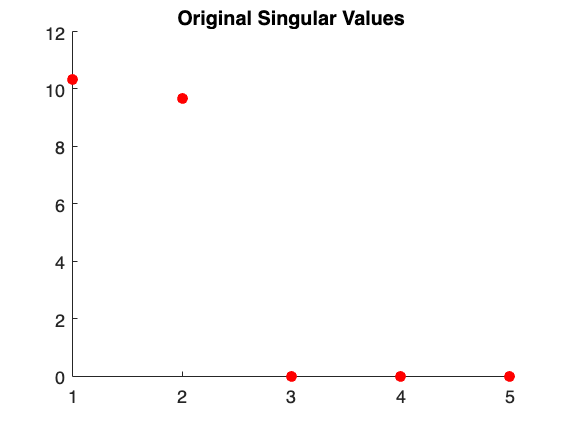

scatter(1:length(matrix_singular), matrix_singular, 'filled', 'red')
title('Original Singular Values')


% samples number doubles
[X_2N, ~, ~] = gendata(M, 2*N, Delta, theta, f, SNR);
matrix_singular = svd(X_2N)

matrix_singular =    14.6073
   13.6612
    0.0000
    0.0000
    0.0000


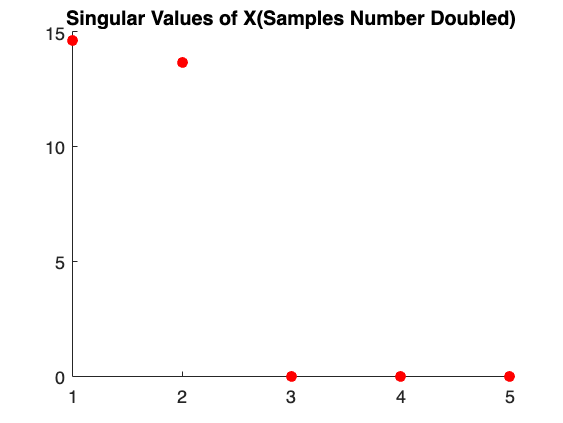

scatter(1:length(matrix_singular), matrix_singular, 'filled', 'red')
title('Singular Values of X(Samples Number Doubled)')


% antennas number doubles
[X_2M, ~, ~] = gendata(2*M, N, Delta, theta, f, SNR);
matrix_singular = svd(X_2M)

matrix_singular =    14.5825
   13.6876
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


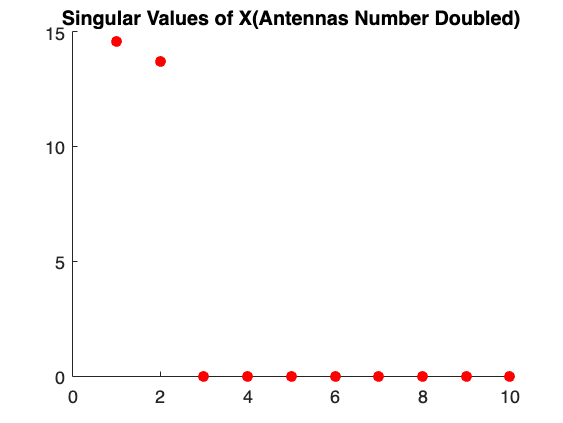

scatter(1:length(matrix_singular), matrix_singular, 'filled', 'red')
title('Singular Values of X(Antennas Number Doubled)')

f_small = [0.1, 0.2]'

f_small =     0.1000
    0.2000


% generate data
[X, ~, ~] = gendata(M, N, Delta, theta, f_small, SNR);

% calculate SVD and plot the singular values
matrix_singular = svd(X)

matrix_singular =    10.3289
    9.6599
    0.0000
    0.0000
    0.0000


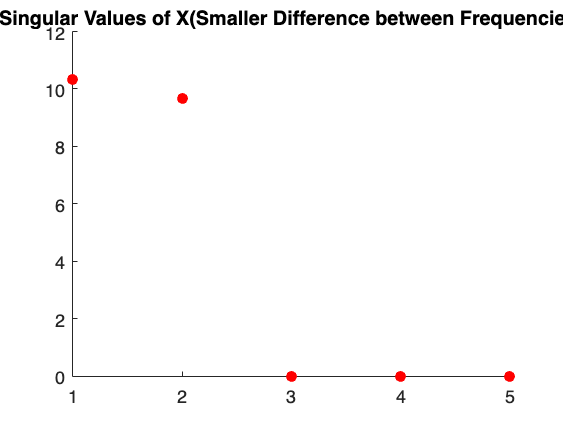

scatter(1:length(matrix_singular), matrix_singular, 'filled', 'red')
title('Singular Values of X(Smaller Difference between Frequencies)')


theta_small = [-21, -109]

theta_small =    -21  -109



% generate data
[X, ~, ~] = gendata(M, N, Delta, theta_small, f, SNR);

% calculate SVD and plot the singular values
matrix_singular = svd(X)

matrix_singular =    11.1789
    8.6622
    0.0000
    0.0000
    0.0000


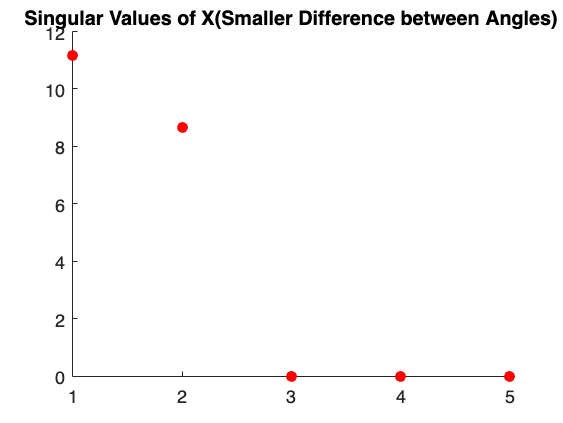

scatter(1:length(matrix_singular), matrix_singular, 'filled', 'red')
title('Singular Values of X(Smaller Difference between Angles)')

## Estimation of Directions and Frequencies

M = 5;
N = 20;
Delta = 0.5;
d = 2;
SNR = inf;

f = [0.3, 0.1]'

f =     0.3000
    0.1000


theta = [-20, 30]'

theta =    -20
    30



[X, ~, ~] = gendata(M, N, Delta, theta, f, SNR);

f_hat = espritfreq(X, d)

f_hat =     0.1000
    0.3000


theta_hat = esprit(X, d)

theta_hat =   -20.0000
   30.0000


## Joint Estimation

M = 5;
N = 20;
d = 2;
m = 3

m = 3

SNR = inf;

theta = [-20, 80]

theta =    -20    80


f = [0.25, 0.6]

f =     0.2500    0.6000



[X, ~, ~] = gendata(M, N, Delta, theta, f, SNR);
[theta_hat,f_hat] = joint(X, d, m)

theta_hat =   -19.9995
   79.9971


f_hat =     0.2500
    0.6000


## Comparison

% Three algorithms
SNR_list = 0:4:20;
M = 3;
N = 20;
d = 2;
theta = [-20, 30];
f = [0.1, 0.12];
m = 5;
max_iter = 1100;

f_esps = zeros(2*length(SNR_list), max_iter);
theta_esps = zeros(2*length(SNR_list), max_iter);
f_joints = zeros(2*length(SNR_list), max_iter);
theta_joints = zeros(2*length(SNR_list), max_iter);

for i = 1:length(SNR_list)
    for j = 1:max_iter
        [X, ~, ~] = gendata(M, N, Delta, theta, f, SNR_list(i));
        f_esps((i-1)*2+1:i*2, j) = espritfreq(X, d);
        theta_esps((i-1)*2+1:i*2, j) = esprit(X, d);
        [theta_joints((i-1)*2+1:i*2 ,j), f_joints((i-1)*2+1:i*2, j)] = joint(X, d, m);
    end
end

% Calculate means and stds
f_esps_means = mean(f_esps, 2);
f_esps_means1 = f_esps_means(1:2:end);
f_esps_means2 = f_esps_means(2:2:end);

f_esps_stds = std(f_esps, 0, 2);
f_esps_stds1 = f_esps_stds(1:2:end);
f_esps_stds2 = f_esps_stds(2:2:end);

theta_esps_means = mean(theta_esps, 2);
theta_esps_means1 = theta_esps_means(1:2:end);
theta_esps_means2 = theta_esps_means(2:2:end);

theta_esps_stds = std(theta_esps, 0, 2);
theta_esps_stds1 = theta_esps_stds(1:2:end);
theta_esps_stds2 = theta_esps_stds(2:2:end);

f_joints_means = mean(f_joints, 2);
f_joints_means1 = f_joints_means(1:2:end);
f_joints_means2 = f_joints_means(2:2:end);

f_joints_stds = std(f_joints, 0, 2);
f_joints_stds1 = f_joints_stds(1:2:end);
f_joints_stds2 = f_joints_stds(2:2:end);

theta_joints_means = mean(theta_joints, 2);
theta_joints_means1 = theta_joints_means(1:2:end);
theta_joints_means2 = theta_joints_means(2:2:end);

theta_joints_stds = std(theta_joints, 0, 2);
theta_joints_stds1 = theta_joints_stds(1:2:end);
theta_joints_stds2 = theta_joints_stds(2:2:end);

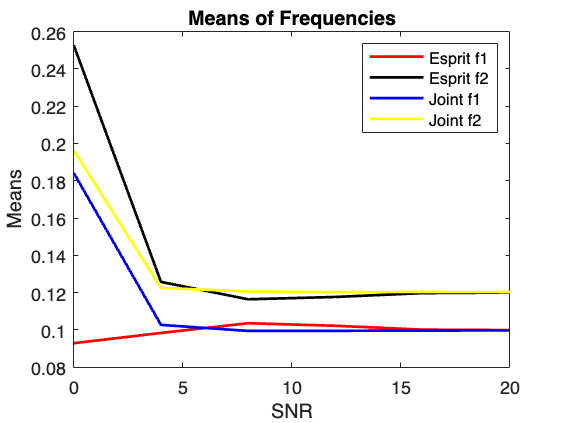

% Plot the means and stds
x = SNR_list;

plot(x, f_esps_means1, 'r', x, f_esps_means2, 'black', x, f_joints_means1, 'b', x, f_joints_means2, 'y', 'LineWidth', 1.5);
xlabel('SNR');
ylabel('Means');
title('Means of Frequencies');
legend('Esprit f1', 'Esprit f2', 'Joint f1', 'Joint f2');

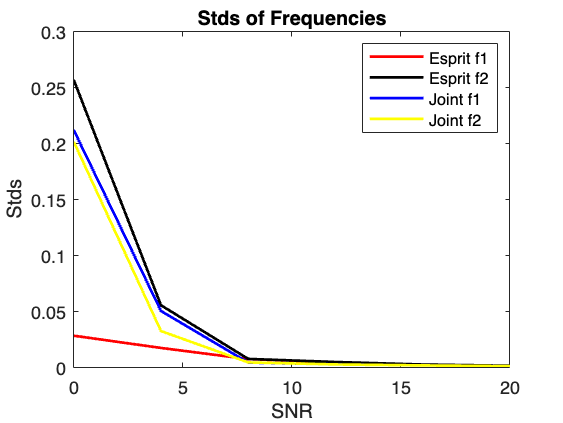


plot(x, f_esps_stds1, 'r', x, f_esps_stds2, 'black', x, f_joints_stds1, 'b', x, f_joints_stds2, 'y', 'LineWidth', 1.5);
xlabel('SNR');
ylabel('Stds');
title('Stds of Frequencies');
legend('Esprit f1', 'Esprit f2', 'Joint f1', 'Joint f2');

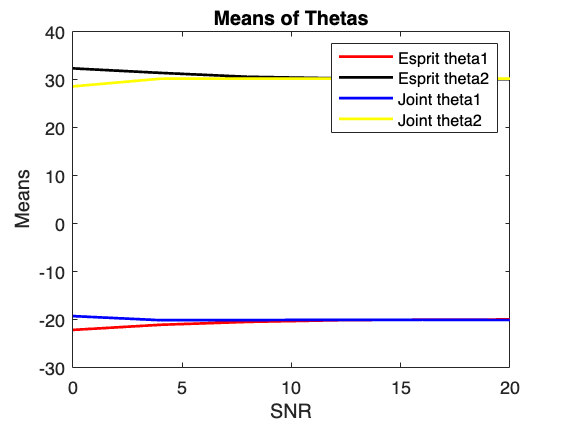


plot(x, theta_esps_means1, 'r', x, theta_esps_means2, 'black', x, theta_joints_means1, 'b', x, theta_joints_means2, 'y', 'LineWidth', 1.5);
xlabel('SNR');
ylabel('Means');
title('Means of Thetas');
legend('Esprit theta1', 'Esprit theta2', 'Joint theta1', 'Joint theta2');

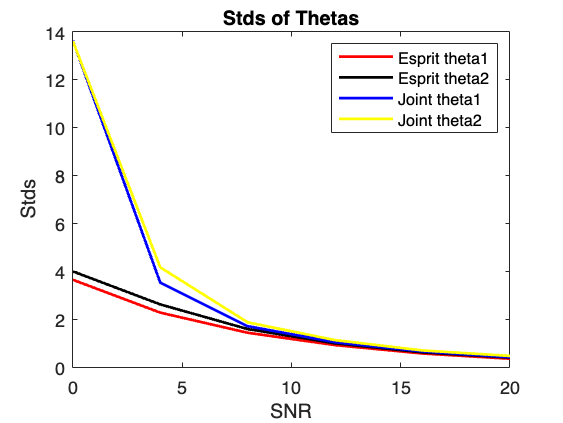


plot(x, theta_esps_stds1, 'r', x, theta_esps_stds2, 'black', x, theta_joints_stds1, 'b', x, theta_joints_stds2, 'y', 'LineWidth', 1.5);
xlabel('SNR');
ylabel('Stds');
title('Stds of Thetas');
legend('Esprit theta1', 'Esprit theta2', 'Joint theta1', 'Joint theta2');

## Zero-forcing Beamformers

M = 3;
N = 20;
d = 2;
Delta = 0.5;
SNR = 10;

theta = [-20, 30]

theta =    -20    30


f = [0.1, 0.12]

f =     0.1000    0.1200



[X, A, S] = gendata(M, N, Delta, theta, f, SNR);

f_hat = espritfreq(X, d)

f_hat =     0.1009
    0.1141


theta_hat = esprit(X, d)

theta_hat =   -19.0631
   28.8000



% Angle estimation zero-forcing beamformer
A_zf = zeros(M, d);
m = 0:M-1;
for i = 1:d
    A_zf(:, i) = exp(2j*pi*m*Delta*sind(theta_hat(i)));
end
W_angle = pinverse(A_zf, d)';
S_hat_angle = W_angle'*X;

W_angle'*A

ans =    0.9940 - 0.0482i   0.0188 - 0.0114i
   0.0159 + 0.0098i   0.9925 + 0.0570i




% Frequency estimation zero-forcing beamformer
S_zf = zeros(d, N);
n = 0:N-1;
for i = 1:d
    S_zf(i, :) = exp(2j*pi*n*f_hat(i));
end
A_zf_hat = X*S_zf'*inv(S_zf*S_zf');
W_freq = pinverse(A_zf_hat, d)';
S_hat_freq = W_freq'*X;

W_freq'*A

ans =    0.9939 - 0.0216i   0.0573 + 0.0416i
   0.1866 + 0.2619i   0.6937 - 0.2573i


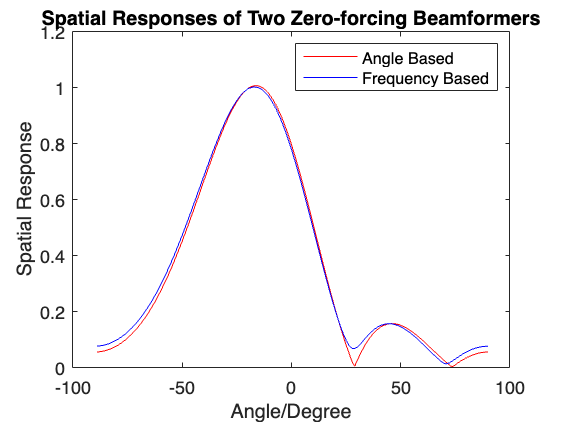

% Spatial Response
angles = -89:1:90;
a_theta = zeros(M, length(angles));

for i = 1:M
    a_theta(i, :) = exp(2j*pi*Delta*(i-1)*sind(angles));
end

Response_angle1 = abs(W_angle(:, 1)'*a_theta);
Response_freq1 = abs(W_freq(:, 1)'*a_theta);

Response_angle2 = abs(W_angle(:, 2)'*a_theta);
Response_freq2 = abs(W_freq(:, 2)'*a_theta);

% Plot spatial responses
plot(angles, Response_angle1, 'r', angles, Response_freq1, 'b');
xlabel('Angle/Degree');
ylabel('Spatial Response');
title('Spatial Responses of Two Zero-forcing Beamformers');
legend('Angle Based', 'Frequency Based');

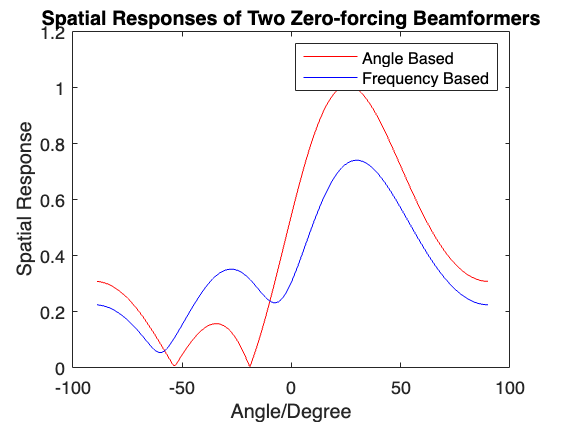


plot(angles, Response_angle2, 'r', angles, Response_freq2, 'b');
xlabel('Angle/Degree');
ylabel('Spatial Response');
title('Spatial Responses of Two Zero-forcing Beamformers');
legend('Angle Based', 'Frequency Based');